# **Contamination modelling and detection**

**Load paths**

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## How to simulate a contamination event

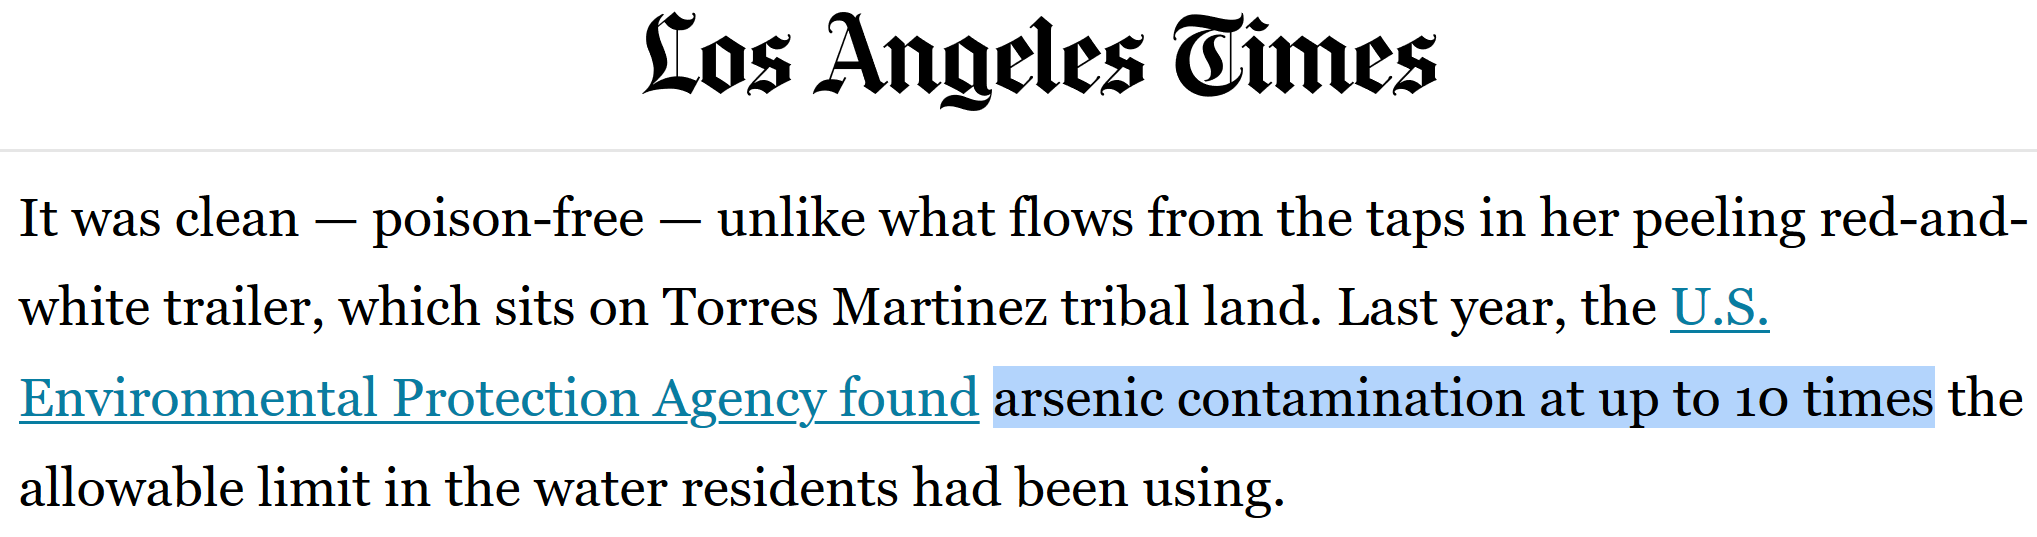

**Create an arsenite contamination event**

Gc = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

EPANET version {20200} loaded (EMT version {v2.2.2 - Last Update: 07/08/2022}).
Loading File "BWSN_Network_1.inp"...
Input File "BWSN_Network_1.inp" loaded successfully.


Gc.loadMSXFile('Arsenite.msx'); % Load MSX file

*Arsenite (As3) reacts with Chlorine (Cl2) and produces Arsenate (As5)*

## **Prepare the simulations**

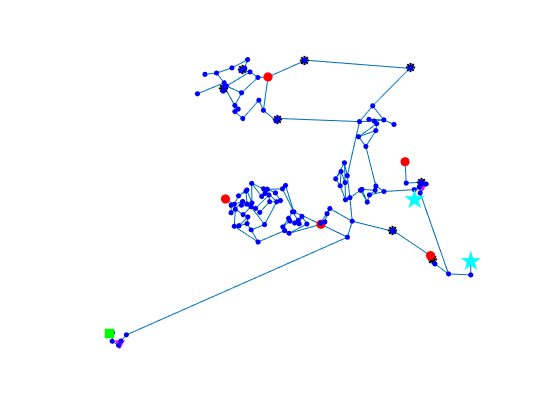

% Sensor locations
sensor_id = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'};
sensor_index = Gc.getNodeIndex(sensor_id);

figure
Gc.plot('highlightnode', sensor_id);


% Simulation Setup
t_d = 5; % days
Gc.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days
Gc.setMSXTimeStep(3600) 

## Contamination scenario

A contamination scenario needs a location (node), a contaminant concentration and a time profile (start and end time)

injection_node = {'JUNCTION-23'}

injection_node = 1×1 cell array
    {'JUNCTION-23'}


injection_conc = 0.05

injection_conc =                       0.05


injection_start_time = 150 

injection_start_time =    150


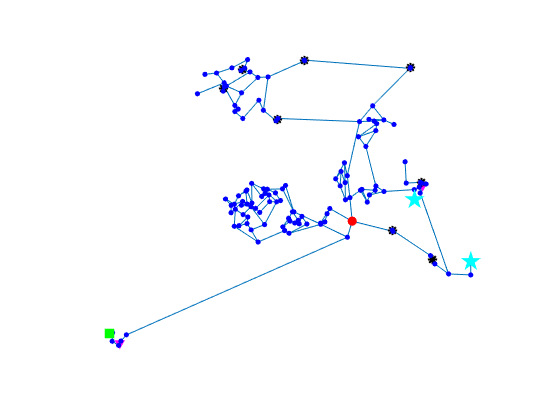

figure
Gc.plot('highlightnode', injection_node);

## **Simulation the even with MSX**

Initialize the contamination vector (binary)

as3_pat = zeros(1, t_d*48); % initialize the vector
as3_pat(injection_start_time:end) = 1; % create the injection pattern 

Simulate the contamination of water with arsenite

% Specify Arsenite injection source
Gc.setMSXSources(injection_node, 'AsIII', 'Setpoint', injection_conc, 'AS3PAT'); 
% Set pattern for injection
Gc.setMSXPattern('AS3PAT',as3_pat);
% Solve hydraulics and MSX quality dynamics
Qmsx = Gc.getMSXComputedQualityNode(sensor_index); 

Plot the results

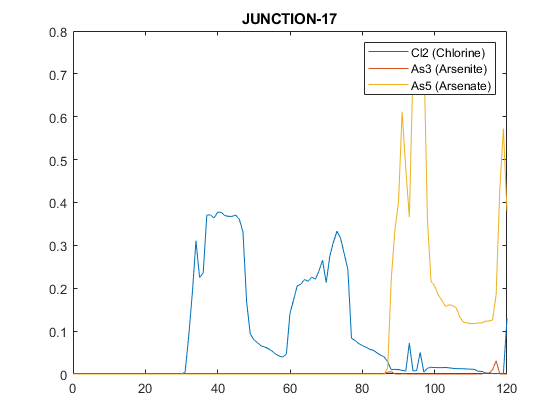

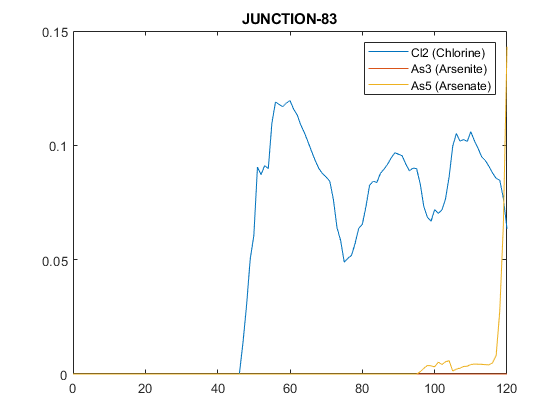

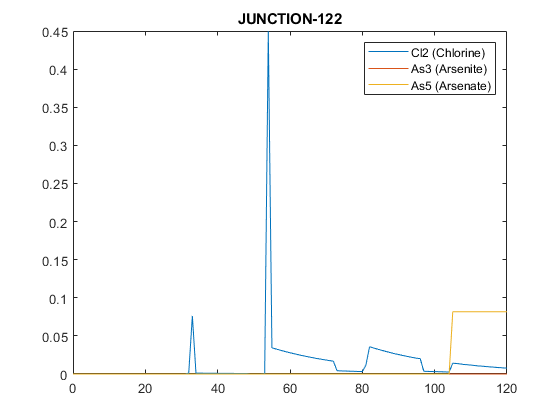

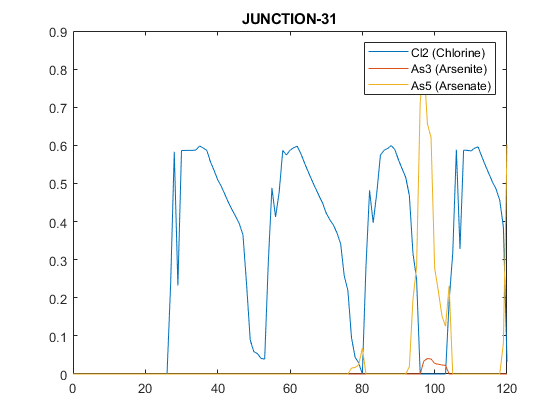

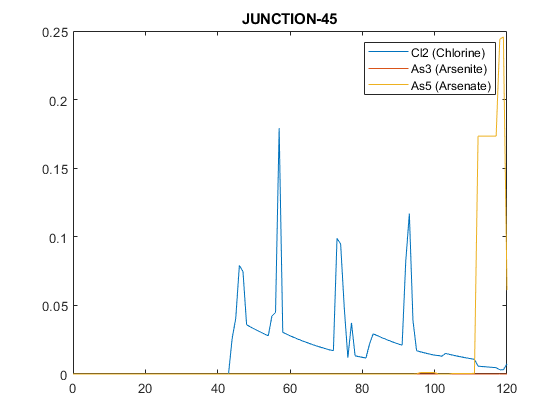

for i = 1:5
    figure
    plot(Qmsx.Time/3600, Qmsx.Quality{i})
    legend('Cl2 (Chlorine)','As3 (Arsenite)', 'As5 (Arsenate)')
    title(sensor_id(i))
end

## **Interval-based contamination detection **

**Initialize the simulation**

rng(1)

%% Load EPANET Network and MSX
Gc = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

EPANET version {20200} loaded (EMT version {v2.2.2 - Last Update: 07/08/2022}).
Loading File "BWSN_Network_1.inp"...
Input File "BWSN_Network_1.inp" loaded successfully.


Gc.loadMSXFile('Arsenite.msx'); % Load MSX file

% Sensor locations
sensor_id = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'}

sensor_id = 1×5 cell array
    {'JUNCTION-17'}    {'JUNCTION-83'}    {'JUNCTION-122'}    {'JUNCTION-31'}    {'JUNCTION-45'}


sensor_index = Gc.getNodeIndex(sensor_id);

%% Simulation Setup
t_d = 5 % days

t_d =      5


Gc.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days

%% Get Network data
demand_pattern = Gc.getPattern;
roughness_coeff = Gc.getLinkRoughnessCoeff;
node_id = Gc.getNodeNameID;

Gc.setMSXTimeStep(3600)

**Setup uncertainties**

%% Scenarios
Ns = 20; % Number of scenarios to simulate
u_p = 0.20 % pattern uncertainty

u_p =                        0.2


u_r = 0.20 % roughness coefficient uncertainty

u_r =                        0.2


**Create the scenarios - first without contamination, to compute the bounds**

max_inj_conc = 0.0

max_inj_conc =      0


inj_start_time = 2*48 % after day 2 (Dt = 30min)

inj_start_time =     96


inj_duration = 24 % maximum duration of 12 hours

inj_duration =     24


% Injection location, magnitude, start time, duration 
inj_sc=[randi(Gc.NodeCount,Ns,1), max_inj_conc*rand(Ns,1), randi(48,Ns,1)+inj_start_time, randi(inj_duration,Ns,1)] 

inj_sc =     54     0   144     3
    93     0   132    10
     1     0   110    17
    40     0   134    10
    19     0   101     2
    12     0   118    13
    25     0   140    16
    45     0   111    13
    52     0   110    23
    70     0   103    15


**Run epochs**

for i = 1:Ns
    disp(['Iteration ', int2str(i)])
    
    % Randomize demands
    r_p = -u_p + 2*u_p.*rand(size(demand_pattern,1),size(demand_pattern,2));
    new_demand_pattern = demand_pattern + demand_pattern.*r_p;
    Gc.setPatternMatrix(new_demand_pattern); % Set new patterns
    
    % Randomize pipe roughness
    r_r = -u_r + 2*u_r.*rand(size(roughness_coeff,1),size(roughness_coeff,2));
    new_roughness_coeff = roughness_coeff + roughness_coeff.*r_r;
    Gc.setLinkRoughnessCoeff(new_roughness_coeff); % Set new roughness coefficients
    
    % Simulate quality with randomized hydraulic parameters
    QQ{i} = Gc.getMSXComputedQualityNode(sensor_index); % Solve hydraulics and MSX quality dynamics
end

Iteration 1
Iteration 2
Iteration 3
Iteration 4
Iteration 5
Iteration 6
Iteration 7
Iteration 8
Iteration 9
Iteration 10
Iteration 11
Iteration 12
Iteration 13
Iteration 14
Iteration 15
Iteration 16
Iteration 17
Iteration 18
Iteration 19
Iteration 20


**Plot the results without contaminations**

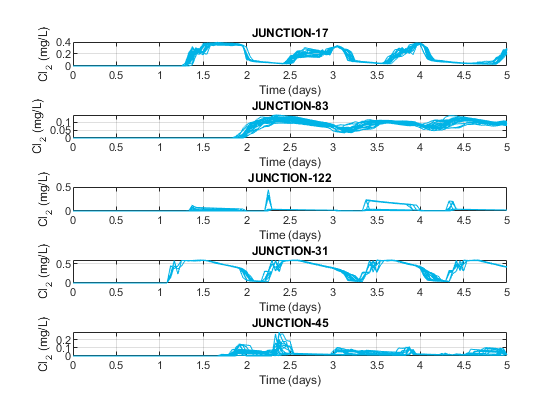

figure
for i = 1:Ns
    for j = 1:length(sensor_index)
       subplot(5,1,j)
       plot(QQ{i}.Time/24/60/60, QQ{i}.Quality{j}(:,1),'-','Color',[0,0.7,0.9]); hold on; grid on
       Qtable{j}(:,i) = QQ{i}.Quality{j}(:,1);
    end
end
for i = 1:length(sensor_index)
   subplot(5,1,i)
   title(sensor_id{i})
   ylabel('Cl_2 (mg/L)')
   xlabel('Time (days)')
end

**Compute the intervals for each sensor**

for j = 1:length(sensor_index)
    % Upper Bound
    UBQ(:,j) = max(Qtable{j},[],2); 
    % Lower Bound    
    LBQ(:,j) = min(Qtable{j},[],2);
end

**Plot the intervals**

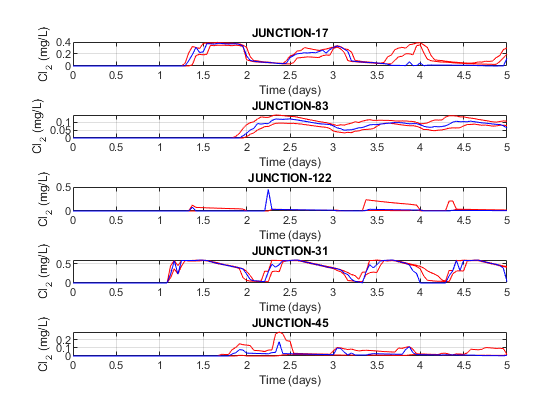

figure
for j = 1:length(sensor_index)
       subplot(5,1,j)
       plot(QQ{i}.Time/24/60/60, UBQ(:,j),'r-'); 
       hold on; 
       plot(QQ{i}.Time/24/60/60, LBQ(:,j),'r-');

       % plot the contamination event simulated earier
       plot(Qmsx.Time/24/60/60, Qmsx.Quality{j}(:,1), 'b-')
       grid on
end
for i = 1:length(sensor_index)
   subplot(5,1,i)
   title(sensor_id{i})
   ylabel('Cl_2 (mg/L)')
   xlabel('Time (days)')
end

## **Contamination detection**

Compare what the model predicts, with what the (chlorine) sensors measure. If the difference is significantly larger, then put a fault warning.


$$e = y - \hat{y}$$


if $e > \bar{\epsilon}$ then fault flag $\phi(k) = 1$

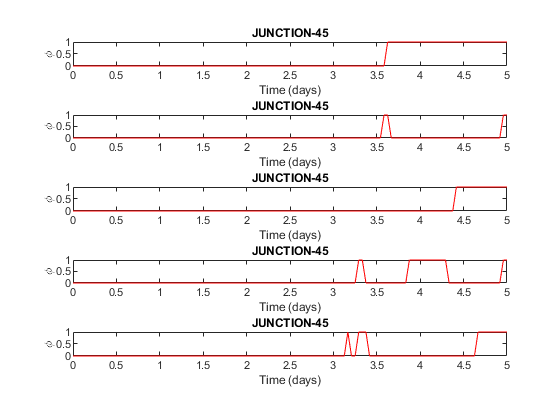

figure
for j = 1:length(sensor_index)   
    % difference between the lower bound and the measured value
    e = LBQ(:,j) - Qmsx.Quality{j}(:,1);
    % create the \phi signal by putting 1 when the error is > 0
    phi = e>0;

    % plot the results
    subplot(5,1,j)
    plot(Qmsx.Time/24/60/60, phi, 'r-')
    title(sensor_id{i})
    ylabel('\phi')
    xlabel('Time (days)')
end